# Resolve Closely Spaced Tones

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a signal with two tones at 25 Hz and 26 Hz.

fs = 75;
t = (0:1/fs:1.6)';
y1 = sin(2*pi*25*t);
y2 = sin(2*pi*26*t);
y = y1 + y2;
n = length(y1);

## Task 1

In the last activity, using a large beta value enabled you to see frequencies that were hidden with small beta values. So why shouldn't you always use large beta values?

In this example, there are two tones in the signal, one at 25 Hz and one at 26 Hz. But in the plot, only one tone is visible.

beta = 0;
[p, f] = periodogram(y, kaiser(n, beta), 2^12, fs);

This code plots the spectrum. The peaks visualized with triangle markers. The correct tone locations are visualized with vertical dashed lines.

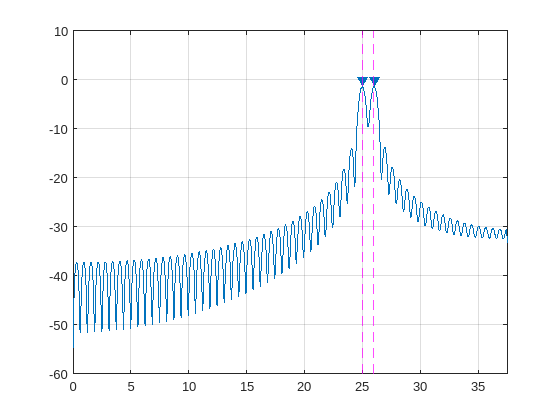

figure;
findpeaks(10*log10(p), f, "NPeaks", 2, "SortStr", "descend")
xline(25, "m--")
xline(26, "m--")